# Loading the Correction coefficients

load doas_correction_coeffs.mat;

# Reading one audio file to get parameters

folder = 'DOA 1 kHz 45deg';
filename = [folder filesep 'Micro 1_001.wav'];
% reading one audio file
[y, Fs] = audioread(filename)

y =    1.0e-04 *

   -0.5341
   -0.4423
   -0.3588
   -0.2062
   -0.4601
   -0.4768
   -0.3135
   -0.5448
    0.1347
   -0.2432


Fs = 48000

% size of the Samples
sizeArray = length(y);
% Number of microphones
N_mic = 16;
% zero array of size
% % (nb_Samples, nb_Micros)
sigArray = zeros(sizeArray, N_mic);

# Reading the 16 audio files

for i = 1:N_mic 
    [y, Fs] = audioread(sprintf([folder '/Micro %d_001.wav'], i));
    sigArray(:, i) = y;
end
sigArray

sigArray =    1.0e-04 *

   -0.5341   -0.5603   -0.2742   -0.0393   -0.0274   -0.1955   -0.2849   -0.1049   -0.1824   -0.0978    0.0322   -0.1073   -0.6306    0.0679    0.0072    0.1383
   -0.4423   -0.0167    0.0715    0.0787   -0.1132   -0.3469    0.1776    0.1657    0.1037   -0.0608   -0.3612    0.0203   -0.6092    0.1049   -0.0441    0.2742
   -0.3588   -0.1752    0.0954    0.0215   -0.1848   -0.5996   -0.3576   -0.5519    0.2503   -0.3672   -0.4256   -0.3874   -0.3755    0.2801    0.1419    0.1824
   -0.2062   -0.2611   -0.4482   -0.0477   -0.4399   -0.4828   -0.2193    0.1812    0.0095   -0.1657    0.0918   -0.3004   -0.5150    0.4196   -0.0978    0.1216
   -0.4601    0.0608   -0.2992   -0.2086   -0.2635   -0.2623   -0.1132    0.1585    0.0751   -0.0131   -0.3552   -0.1323   -0.1502   -0.0155   -0.2789   -0.0477
   -0.4768    0.0918   -0.1931   -0.3457   -0.6342   -0.2325   -0.3517    0.1025   -0.0334   -0.1621   -0.2754   -0.3314   -0.4828    0.3242    0.0191   -0.3874
   -0.313

# Calculating the Correction Coefficients

Y_ref_rms = rms(y(Fs : end)); % Fs:end to jump first second(transient)
MAT_rms = rms(sigArray(Fs:end, :)); % sigArray(rows, cols)

correct_coeffs = MAT_rms.^(-1).* Y_ref_rms; 

% saving the correction coeffs as CORRECT_COEFFS % IF needed
save doas_correction_coeffs correct_coeffs


# Applying the correction to the signal

% the entire signal corrected
sigCorrected = zeros(sizeArray, N_mic);

for i = 1:N_mic
    sigCorrected(:, i) = sigArray(:, i) * correct_coeffs(i);
end
sigCorrected

sigCorrected =    1.0e-03 *

   -0.0891   -0.1287   -0.0559   -0.0066   -0.0067   -0.0375   -0.0442   -0.0109   -0.0236   -0.0127    0.0038   -0.0160   -0.0911    0.0072    0.0006    0.0138
   -0.0738   -0.0038    0.0146    0.0132   -0.0275   -0.0665    0.0275    0.0173    0.0134   -0.0079   -0.0428    0.0030   -0.0880    0.0111   -0.0039    0.0274
   -0.0599   -0.0403    0.0194    0.0036   -0.0449   -0.1149   -0.0555   -0.0575    0.0323   -0.0476   -0.0504   -0.0579   -0.0542    0.0296    0.0126    0.0182
   -0.0344   -0.0600   -0.0914   -0.0080   -0.1068   -0.0925   -0.0340    0.0189    0.0012   -0.0215    0.0109   -0.0449   -0.0744    0.0443   -0.0087    0.0122
   -0.0768    0.0140   -0.0610   -0.0351   -0.0640   -0.0503   -0.0176    0.0165    0.0097   -0.0017   -0.0421   -0.0198   -0.0217   -0.0016   -0.0248   -0.0048
   -0.0796    0.0211   -0.0394   -0.0582   -0.1540   -0.0446   -0.0545    0.0107   -0.0043   -0.0210   -0.0326   -0.0495   -0.0697    0.0342    0.0017   -0.0387
   -0

# Estimate the spacial location of the loudspeaker (in azimuth)

% One type of microphone
mic = phased.OmnidirectionalMicrophoneElement('FrequencyRange', [20 20e3])

mic =   phased.OmnidirectionalMicrophoneElement with properties:

    FrequencyRange: [20 20000]
       BackBaffled: false


% the microphone array
%%% TODO: check if axis is correct %%% according to the diff axis: x, y or z, it changes to 60, 30, 46
arr_microphones = phased.ULA('NumElements', 16, 'ElementSpacing', 0.07, 'ArrayAxis','x',...
    'Element', mic)

arr_microphones =   phased.ULA with properties:

           Element: [1×1 phased.OmnidirectionalMicrophoneElement]
       NumElements: 16
    ElementSpacing: 0.0700
         ArrayAxis: 'x'
             Taper: 1


% https://nl.mathworks.com/help/phased/ug/beamscan-direction-of-arrival-estimation.html
% https://nl.mathworks.com/help/phased/ref/beamscanspectrum.html
% https://nl.mathworks.com/help/phased/ref/phased.beamscanestimator-system-object.html
c = 340;
frequencies = 1000;
estimator = phased.BeamscanEstimator('OperatingFrequency',frequencies, ...
    'SensorArray', arr_microphones,'PropagationSpeed', c, ...
    'DOAOutputPort',true) % NumSignals=1  due to, we only have the blank noise/tune

estimator =   phased.BeamscanEstimator with properties:

                 SensorArray: [1×1 phased.ULA]
            PropagationSpeed: 340
          OperatingFrequency: 1000
         NumPhaseShifterBits: 0
    ForwardBackwardAveraging: false
            SpatialSmoothing: 0
                  ScanAngles: [1×181 double]
               DOAOutputPort: true
                  NumSignals: 1


% Estimating the angle
[y, sigang] = estimator(sigCorrected);
sigang

sigang = -60

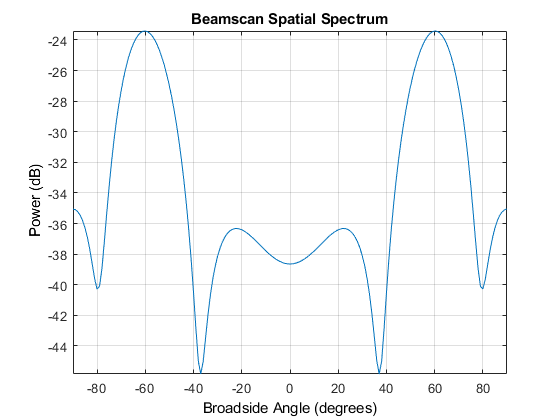

figure(2)
plotSpectrum(estimator)

# Plotting the Directivety Angle

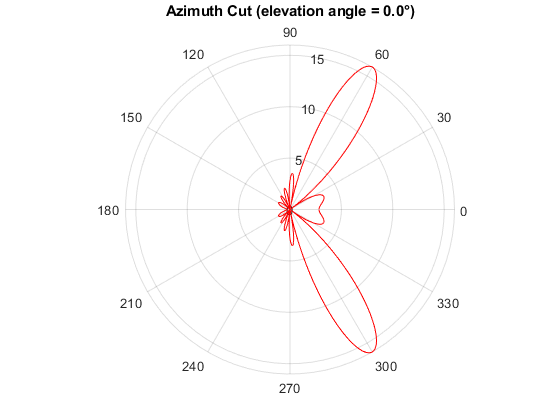

figure(3)
directivity_plot(16, 0.07, frequencies, sigang, c, 'r')